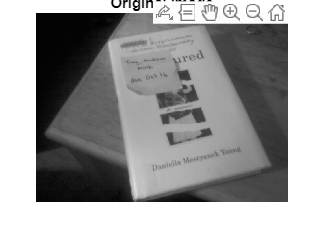

imdata = imread('book.jpg');
image = rgb2gray(imdata);
image = im2double(image);
F = fft2(image);
F_shifted = fftshift(abs(ft_X));
F_log = log(1 + F_shifted);

magnitude = abs(F_shifted);
magnitude_log = log(1 + magnitude); % Add 1 to avoid log(0)

% Display the original image
figure;
imshow(image);
title('Original Image');

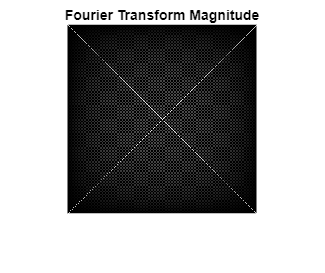


% Display the Fourier Transform magnitude
figure;
imshow(magnitude_log, []);
title('Fourier Transform Magnitude');